clear all
close all
warning off
%C6
g = 9.82;
rho = 1000;
q = [0:0.5:3.5]'

q =          0
    0.5000
    1.0000
    1.5000
    2.0000
    2.5000
    3.0000
    3.5000


p6 = rho*g/10^5.*[5.75 5.85 5.9 5.7 5.1 4.25 3.3 2.4]'

p6 =     0.5646
    0.5745
    0.5794
    0.5597
    0.5008
    0.4173
    0.3241
    0.2357


p5 = rho*g/10^5.*[4.1 4.2 4.2 4 3.55 3 2.3 1.55]'

p5 =     0.4026
    0.4124
    0.4124
    0.3928
    0.3486
    0.2946
    0.2259
    0.1522


p3 = rho*g/10^5.*[1.75 1.85 1.7 1.3 0.95]'

p3 =     0.1719
    0.1817
    0.1669
    0.1277
    0.0933


p = [p6;p5;p3]

p =     0.5646
    0.5745
    0.5794
    0.5597
    0.5008
    0.4173
    0.3241
    0.2357
    0.4026
    0.4124


q = [q;q;q(1:5)]

q =          0
    0.5000
    1.0000
    1.5000
    2.0000
    2.5000
    3.0000
    3.5000
         0
    0.5000



w6 = repmat(80,8,1);
w5 = repmat(69,8,1);
w3 = repmat(48,5,1);
w = [w6;w5;w3]

w =     80
    80
    80
    80
    80
    80
    80
    80
    69
    69



A = [w.*w w.*q q.*q]

A = 	1.0e+03 *

    6.4000         0         0
    6.4000    0.0400    0.0003
    6.4000    0.0800    0.0010
    6.4000    0.1200    0.0022
    6.4000    0.1600    0.0040
    6.4000    0.2000    0.0063
    6.4000    0.2400    0.0090
    6.4000    0.2800    0.0123
    4.7610         0         0
    4.7610    0.0345    0.0003


b = p;
x = inv(A'*A)*A'*b

x =     0.0001
    0.0004
   -0.0323


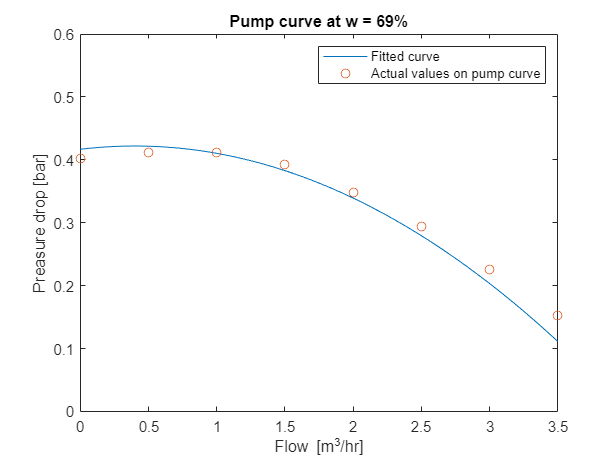


pumpcurve = @(q,w) x(1)*w^2+x(2)*q*w+x(3)*q^2;

pumpcurve6 = @(q) x(1)*80^2+x(2)*q*80+x(3)*q^2;

pumpcurve5 = @(q) x(1)*69^2+x(2)*q*69+x(3)*q^2;

fplot(pumpcurve5)
hold on
scatter([0:0.5:3.5],p5)
hold off
xlim([0 3.5])
ylim([0 1])
title('')
title('Pump curve at w = 69%')
ylabel('Preasure drop [bar]')
xlabel('Flow [m^3/hr]')
yaxis([0 0.6])
legend('Fitted curve','Actual values on pump curve')